% 1次元複素数ベクトルのプロット
real_x = real(x_true)

real_x =     0.4901
    0.5862
    0.5045
    0.7103
    0.7913
   -1.7470
   -0.8507
   -0.0267
    3.0716
    0.2987


imag_x = imag(x_true)

imag_x =    -0.2226
    0.2280
    1.2905
    0.4026
    0.9072
    0.1560
   -0.5679
   -1.3822
   -0.9617
    0.9445


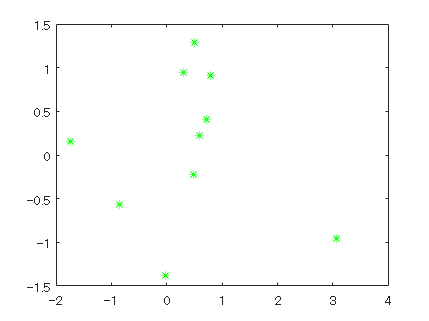

plot(real_x, imag_x, 'g*')

numrows = 3;
numcols = 4;
image = [1 2 3 4; 5 6 7 8; 9 10 11 12]

image =      1     2     3     4
     5     6     7     8
     9    10    11    12


x = rand(12, 1, "like", 1i)

x =    0.2102 + 0.4532i
   0.9053 + 0.3662i
   0.1810 + 0.7774i
   0.2547 + 0.2562i
   0.5746 + 0.8902i
   0.8225 + 0.3676i
   0.8166 + 0.2700i
   0.2003 + 0.6679i
   0.1712 + 0.7341i
   0.1686 + 0.2028i


recovered_image = reshape(x,numrows,numcols)

recovered_image =    0.2102 + 0.4532i   0.2547 + 0.2562i   0.8166 + 0.2700i   0.1686 + 0.2028i
   0.9053 + 0.3662i   0.5746 + 0.8902i   0.2003 + 0.6679i   0.5691 + 0.5727i
   0.1810 + 0.7774i   0.8225 + 0.3676i   0.1712 + 0.7341i   0.0655 + 0.4126i


rotation = sign(recovered_image(:)'*image(:))

rotation = 0.5785 - 0.8157i

recovered_image = real(rotation*recovered_image)

recovered_image =     0.4913    0.3564    0.6926    0.2630
    0.8225    1.0585    0.6606    0.7963
    0.7388    0.7757    0.6978    0.3744


x0 = (1:12)';
A = A(eye(size(x0,1)))
num_fourier_masks = 8;
masks = (random_vars<.5)*2 - 1;


m = 10;
n = 4;
x = (1:4)';
[x;zeros(m-n,1)]

ans =      1
     2
     3
     4
     0
     0
     0
     0
     0
     0


fft([x;zeros(m-n,1)])

ans =   10.0000 + 0.0000i
   2.3090 - 7.8330i
  -4.0451 - 1.3143i
   1.1910 + 2.2124i
   1.5451 - 2.1266i
  -2.0000 + 0.0000i
   1.5451 + 2.1266i
   1.1910 - 2.2124i
  -4.0451 + 1.3143i
   2.3090 + 7.8330i


ifft(fft([x;zeros(m-n,1)]))

ans =     1.0000
    2.0000
    3.0000
    4.0000
   -0.0000
         0
   -0.0000
    0.0000
    0.0000
         0


numrows = 3;
numcols = 4;
measurements = zeros(2, 3, 4);
measurements(1,:,:) = reshape(1:12, [numrows, numcols]);
measurements(2,:,:) = reshape(-12:-1, [numrows, numcols]);
asd
measurements = measurements(:)

measurements =      1
   -12
     2
   -11
     3
   -10
     4
    -9
     5
    -8


num_fourier_masks = 2;
measurements = reshape(measurements,[num_fourier_masks,numrows,numcols])

measurements = measurements(:,:,1) =

     1     2     3
   -12   -11   -10


measurements(:,:,2) =

     4     5     6
    -9    -8    -7


measurements(:,:,3) =

     7     8     9
    -6    -5    -4


measurements(:,:,4) =

    10    11    12
    -3    -2    -1
